# **Relatório do Laboratório de Sinais e Sistemas**

**Q1.1**

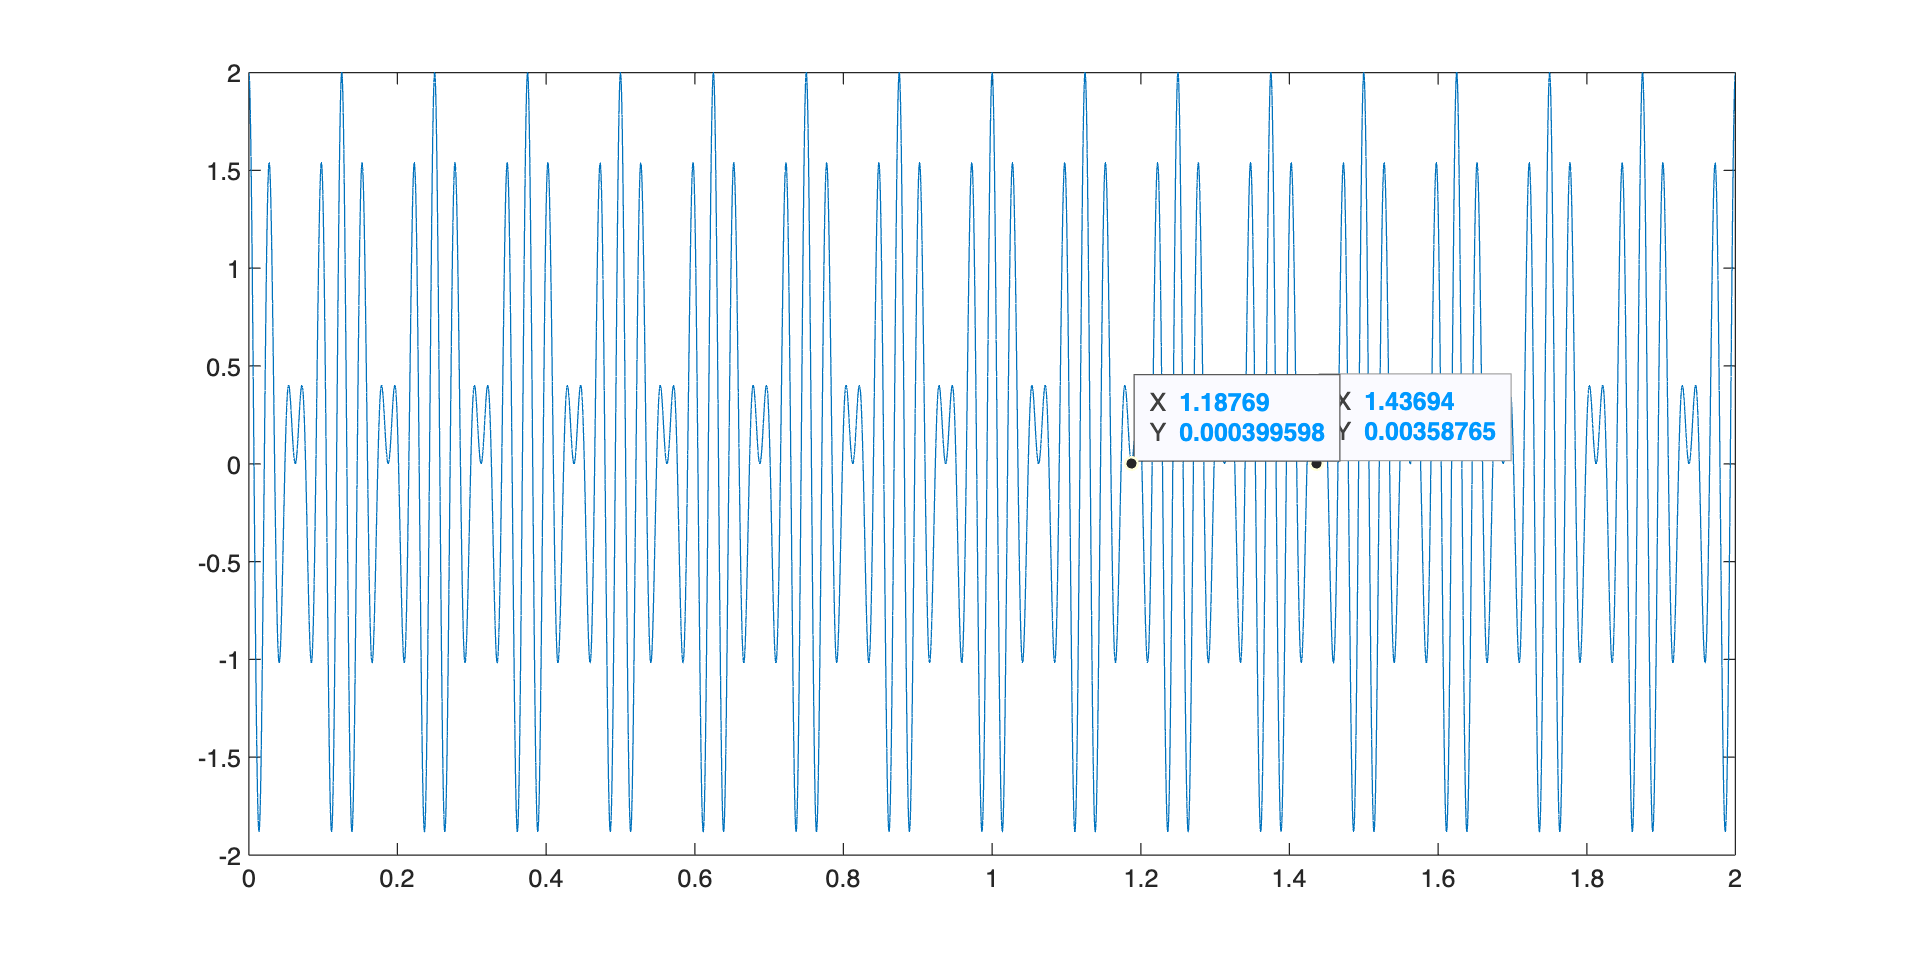

samplerateQ1 = 16e3; % Hz
t = (0:1/samplerateQ1:2); % s
f1 = 32; % Hz
f2 = 40; % Hz
noteSeq = cos(2*pi*f1*t) + cos(2*pi*f2*t);
figure('Units', 'pixels', 'Position', [0, 0, 1000, 500]); 
plot(t,noteSeq)

%[xi, yi] = ginput; >> METER DATA TIPS
period = mean(diff(xi))

Unrecognized function or variable 'xi'.

Teoricamente, o período fundamental do sinal é o menor múltiplo comum (MMC) dos períodos fundamentais de cada cosseno.

Ao trabalhar com números racionais (como os períodos fundamentais de cada cosseno, que são o inverso das suas frequências), temos:


$$\text{MMC} = \frac{\text{MMC dos numeradores (= 1)}}{\text{MDC dos denominadores}}$$


theoretical_period = 1/gcd(f1, f2)

O período que medimos, como a média das diferenças subsequentes entre "localizações periódicas" no sinal, concorda com o período teórico que calculámos acima.

% "Localizações Periódicas" é muito mau ahhahah tenho de mudar

**Q1.2**

% Code
% Code
% Code

**Q1.3**

A4 = 440; % Hz
function frequency = noteFrequencyFromHalfsteps(no_halfsteps)
    A4 = 440; % Hz
    ratio = 2^(1/12);    
    frequency = A4 * ratio^no_halfsteps;
end

C4 = noteFrequencyFromHalfsteps(-9);
E4 = noteFrequencyFromHalfsteps(-5);
Fs4 = noteFrequencyFromHalfsteps(-3);
G4 = noteFrequencyFromHalfsteps(-2);
B4 = noteFrequencyFromHalfsteps(2);
F4 = noteFrequencyFromHalfsteps(-4);


$$\text{R(0.7), E4(0.25), E4(0.25), F4(0.25), F\#4(0.5), A4(0.25),} \\

\text{F\#4(0.25), A4(0.25), F\#4(0.25), F\#4(0.25), F4(0.25),} \\

\text{E4(0.25), B4(0.25), E4(0.25), E4(0.5), R(0.7)}$$


noteSeq = seqsin(samplerateQ1, 0, 0.7, E4, 0.25, E4, 0.25, F4, 0.25, Fs4, 0.5, A4, 0.25, ...
            Fs4, 0.25, A4, 0.25, Fs4, 0.25, Fs4, 0.25, F4, 0.25, ...
            E4, 0.25, B4, 0.25, E4, 0.25, E4, 0.5, 0, 0.7);
soundsc(noteSeq, samplerateQ1)

Device Error: Internal Device error

**Q1.4**

% Code
% Code
% Code

u = @(t) (t >= 0);
s = @(t) (t >= 0).*t; % Unit ramp
uD = @(t,D) (1/D)*(s(t+D/2)-s(t-D/2)); % Approximate unit step
duD = @(t,D,h) (uD(t+h/2,D)-uD(t-h/2,D))/h; % Numeric derivative
deltaD = @(t,D) duD(t,D,1e-6); % Approximate unit impulse

**Q2.1**

system1 = @(x) filter([1 zeros(1,round(0.4*samplerateQ1) - 1) 0.7],1,x);
[x,samplerateQ2] = audioread('echoin.wav');

soundsc([x; system1(x)], samplerateQ2); 

% Em vez de só ouvir o sinal transformado, ouvimos o sinal de entrada 
% antes do sinal de saída - [entrada; saída] -, para poder comparar os dois.

Ao ouvir o resultado da aplicação do sinal lido do ficheiro `echoin.wav` ao sistema `system1`, conseguimos isolar o sinal original, no entanto, ouvimo-lo repetido pouco depois, como que um eco, menos intenso.

Perante o sistema definido, isto faz todo o sentido. Analisemos porquê.

O sistema sobrepõe 2 sinais: o sinal de entrada e uma transformação do sinal de entrada pesado por uma constante. Nesta última parcela, ao usar uma constante $<1$, o sinal é atenuado e, com uma transformação na variável independente, é ainda atrasado. Estes dois fenómenos faz com que, ao sinal de entrada, estejamos a somar algo que simule o seu eco.

**Q2.2**

A figura parece representar uma sobreposição de inúmeros impulsos com diferentes atrasos, que diminuem progressivamente  ($\sum\limits_i a_i \cdot\delta(t-t_{0_i})$), com $a_{i+1}$ aproximadamente menor que $a_i$). 

Por isto, observamos menos impulsos mais fortes para atrasos pequenos, e mais impulsos mais fracos para atrasos maiores.

Este padrão ocorre devido ao comportamento físico do sinal numa sala como a descrita. Ao ser emitido pela fonte, o sinal reflete-se nas paredes, onde é parcialmente absorvido e atenuado a cada reflexão. Assim, o sinal muda de direção e perde intensidade ao longo do tempo. Quanto mais reflexões o sinal sofre, maior distância percorre e, consequentemente, maior é o atraso antes de atingir o recetor.

Inicialmente, para atrasos pequenos, há menos impulsos porque o sinal segue caminhos diretos e curtos até ao recetor. Estes caminhos envolvem menos reflexões, resultando em menor atenuação. Com o passar do tempo, as frentes de onda que seguiram caminhos mais indiretos, sofrendo múltiplas reflexões, começam a chegar ao recetor. Estes sinais percorreram distâncias maiores e foram mais atenuados, o que resulta em impulsos mais fracos com atrasos maiores. São mais impulsos pois há muitas direções diferente das "ótimas", que levam aos caminhos mais curtos.

Assim, a resposta ao impulso reflete a distribuição das trajetórias que o sinal percorre.

**Q2.3**

**Q2.4**